%Förbredelse uppgifter
% fråga 1: imagesc behöver en m-by-n matris

% fråga 2: colormap bestämmer färggradienten. Colormap gray mappar bilden i
% gråskala dvs svart till vit.

% fråga 3: nej :3


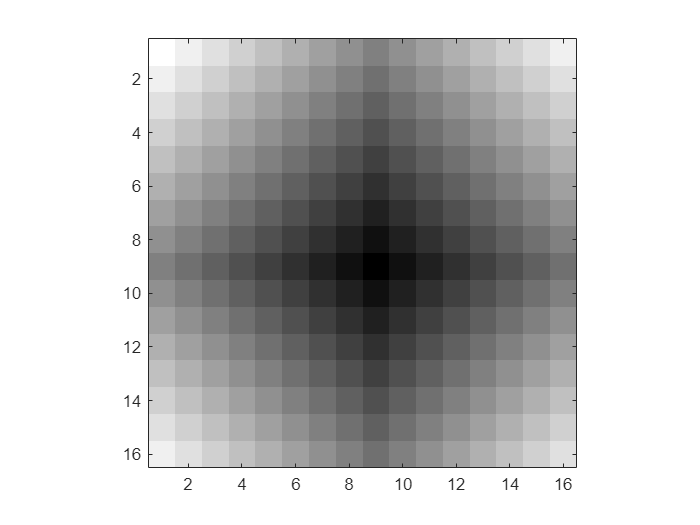

% 1.3
clear;
distance_map = zeros(16, 16);
for n  = 1:16
 for m = 1:16
    distance_map(n,m) = manhattan(n, m, 9, 9);
 end
end
figure;
imagesc(distance_map);
axis image;
colormap gray;

k = 1;
mask = (distance_map <= k);

% 1.4
load("waves.mat");
ftwaves = fft2(waves)

ftwaves = 	1.0e+06 *

   1.2422 + 0.0000i  -0.8677 + 0.0083i   0.3374 - 0.0225i  -0.0622 + 0.0021i   0.0028 - 0.0006i  -0.0073 - 0.0015i   0.0138 + 0.0040i  -0.0065 - 0.0090i  -0.0020 + 0.0185i   0.0022 - 0.0137i   0.0004 - 0.0000i  -0.0001 + 0.0044i   0.0023 - 0.0006i  -0.0064 - 0.0039i   0.0067 + 0.0022i  -0.0035 + 0.0015i   0.0061 + 0.0043i  -0.0071 - 0.0125i   0.0069 + 0.0106i  -0.0047 - 0.0038i  -0.0008 + 0.0022i   0.0034 + 0.0022i   0.0006 - 0.0117i  -0.0059 + 0.0097i   0.0037 - 0.0008i   0.0039 - 0.0025i   0.0028 + 0.0068i  -0.0081 - 0.0027i   0.0044 - 0.0111i  -0.0011 + 0.0147i   0.0100 - 0.0077i  -0.0156 + 0.0034i   0.0102 + 0.0030i  -0.0036 - 0.0017i   0.0080 - 0.0046i  -0.0175 + 0.0110i   0.0198 - 0.0130i  -0.0096 + 0.0124i  -0.0098 - 0.0047i   0.0110 + 0.0019i   0.0033 - 0.0057i  -0.0052 + 0.0012i   0.0007 + 0.0092i   0.0019 - 0.0087i   0.0042 + 0.0023i  -0.0149 - 0.0038i   0.0116 + 0.0000i  -0.0047 + 0.0021i   0.0075 + 0.0081i  -0.0032 - 0.0027i
  -0.8065 - 0.3502i   0.593

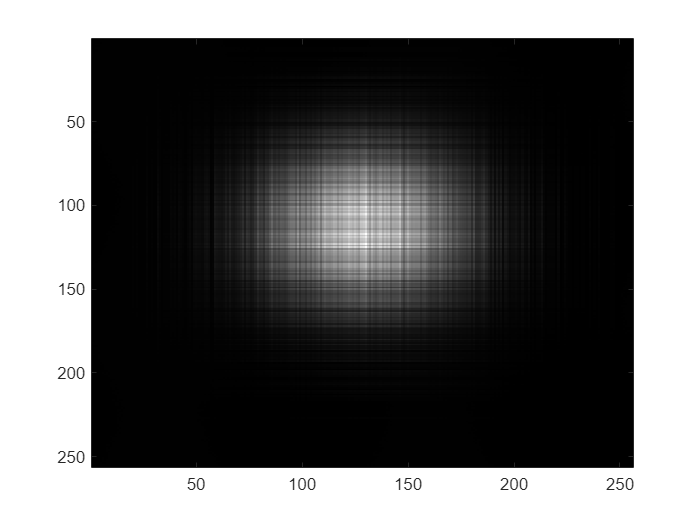


imagesc(waves);


abs(ftwaves)

ans = 	1.0e+06 *

    1.2422    0.8677    0.3382    0.0623    0.0029    0.0074    0.0143    0.0111    0.0186    0.0139    0.0004    0.0044    0.0024    0.0075    0.0070    0.0038    0.0075    0.0143    0.0126    0.0061    0.0024    0.0041    0.0117    0.0114    0.0038    0.0046    0.0073    0.0085    0.0119    0.0148    0.0126    0.0160    0.0106    0.0040    0.0092    0.0206    0.0237    0.0157    0.0109    0.0112    0.0066    0.0054    0.0092    0.0089    0.0048    0.0154    0.0116    0.0052    0.0110    0.0042
    0.8792    0.6443    0.2502    0.0462    0.0022    0.0055    0.0106    0.0082    0.0138    0.0104    0.0003    0.0033    0.0018    0.0056    0.0052    0.0028    0.0056    0.0106    0.0094    0.0045    0.0018    0.0030    0.0087    0.0084    0.0028    0.0035    0.0054    0.0063    0.0088    0.0110    0.0094    0.0119    0.0079    0.0030    0.0068    0.0153    0.0176    0.0116    0.0081    0.0083    0.0049    0.0040    0.0068    0.0066    0.0035    0.0114    0.0086    0.0038 

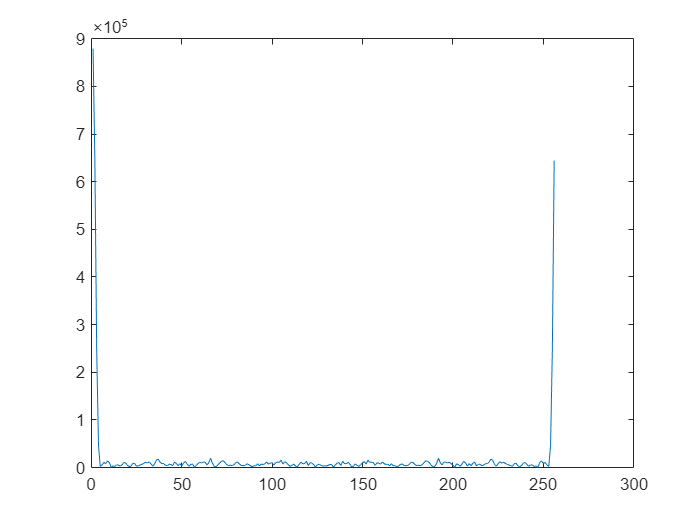

plot(abs(ftwaves(2,:)));

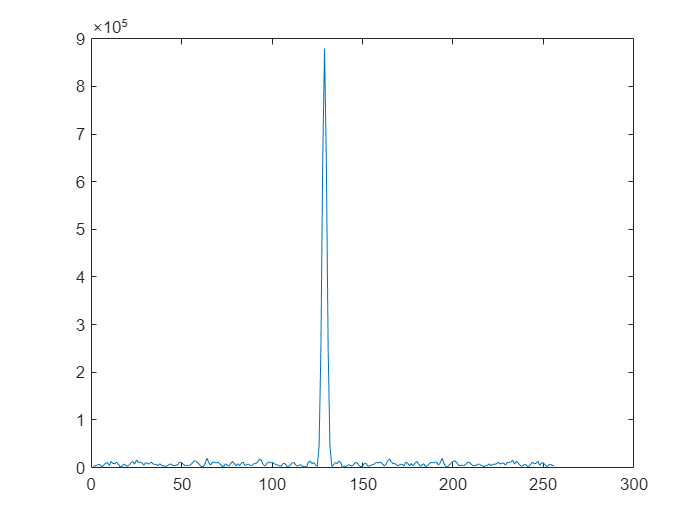

plot(abs(fftshift(ftwaves(2,:))));

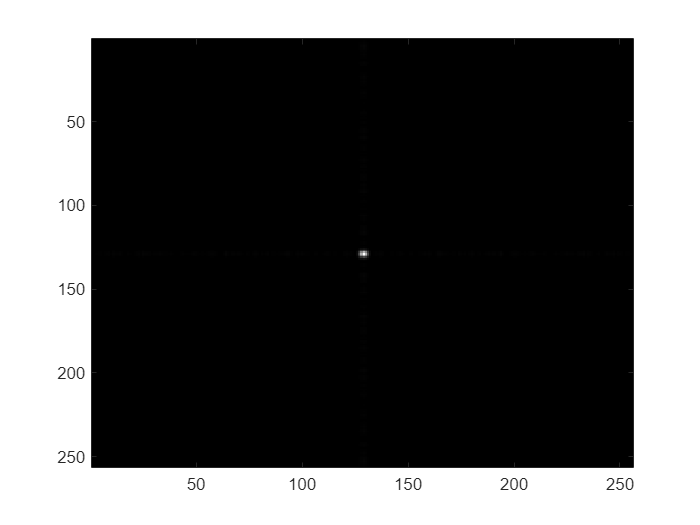


ftshitwaves = fftshift(ftwaves);
imagesc(abs(ftshitwaves));

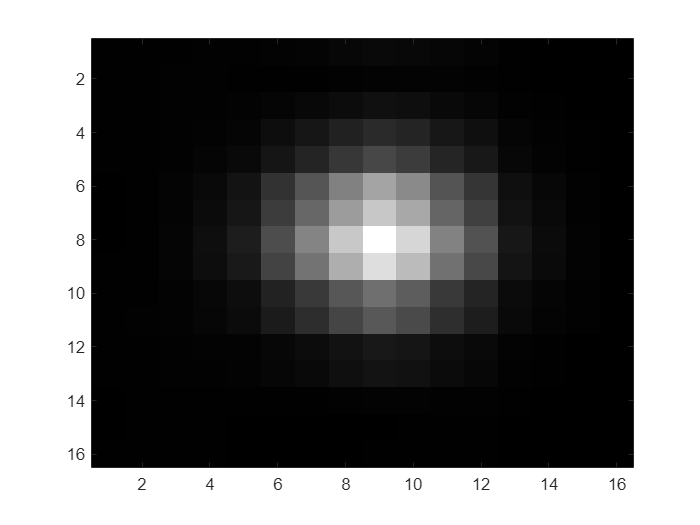


shortwaves = waves(1:16:256,1:16:256);
imagesc(abs(shortwaves));

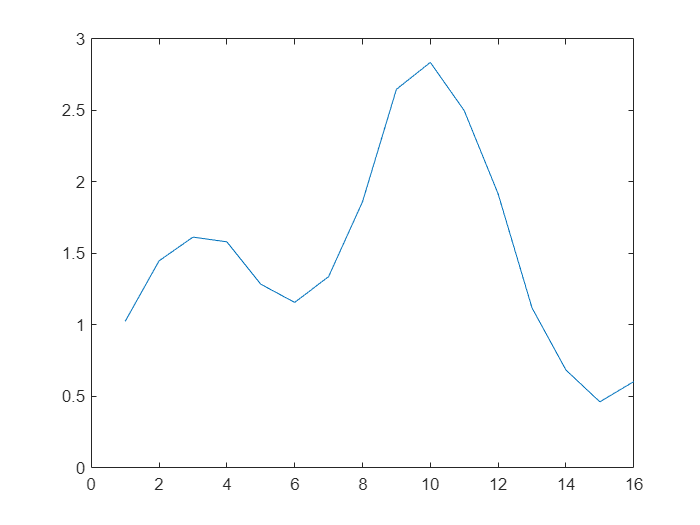

plot(abs(shortwaves(2,:)));

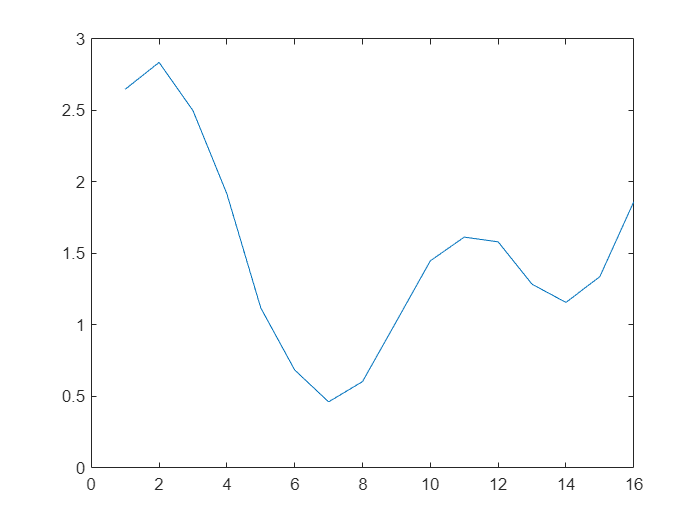

plot(abs(fftshift(shortwaves(2,:))));



sus = ifft2(fftshift(fftshift(fft2(shortwaves))));
gus = ifft2(fft2(shortwaves)); % ^^ the same thing :) fftshift two times reveses the function
pus = fftshift(fftshift(shortwaves));
kus = shortwaves;
%sus = gus = pus = kus

imagesc(gus)

imagesc(sus)

%sus - gus = 0
ftshortwaves = fft2(shortwaves);
ftshortwaves0 = fftshift(ftshortwaves) .* mask

ftshortwaves0 = 	1.0e+03 *

   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i


% rec0 = shortwaves * mask, shows the part of shortwaves which the mask lets through
rec0 = ifft2(fftshift(ftshortwaves0));

%imagesc(ftshortwaves0); % shows the dot which the mask lets through
abs(rec0)

ans =    29.2398   27.3218   21.8974   13.7923    4.2404    5.3039   13.3878   18.7804   20.6609   18.7429   13.3185    5.2134    4.3384   13.8828   21.9666   27.3593
   23.7090   21.7910   16.3666    8.2615    1.2903   10.8347   18.9185   24.3112   26.1917   24.2737   18.8493   10.7442    1.1923    8.3520   16.4359   21.8285
   15.6697   13.7518    8.3273    0.2222    9.3296   18.8740   26.9578   32.3505   34.2310   32.3130   26.8885   18.7834    9.2316    0.3127    8.3966   13.7893
    6.3459    4.4279    0.9966    9.1017   18.6535   28.1978   36.2817   41.6744   43.5548   41.6369   36.2124   28.1073   18.5555    9.0111    0.9273    4.4654
    2.8431    4.7611   10.1856   18.2907   27.8425   37.3868   45.4707   50.8634   52.7439   50.8259   45.4014   37.2963   27.7445   18.2002   10.1163    4.7236
   10.4983   12.4163   17.8408   25.9459   35.4977   45.0420   53.1259   58.5186   60.3990   58.4811   53.0566   44.9515   35.3997   25.8553   17.7715   12.3788
   15.4543   17.3723   22.79

real(rec0)

ans =   -29.2398  -27.3218  -21.8974  -13.7923   -4.2404    5.3039   13.3878   18.7804   20.6609   18.7429   13.3185    5.2134   -4.3384  -13.8828  -21.9666  -27.3593
  -23.7090  -21.7910  -16.3666   -8.2615    1.2903   10.8347   18.9185   24.3112   26.1917   24.2737   18.8493   10.7442    1.1923   -8.3520  -16.4359  -21.8285
  -15.6697  -13.7518   -8.3273   -0.2222    9.3296   18.8740   26.9578   32.3505   34.2310   32.3130   26.8885   18.7834    9.2316   -0.3127   -8.3966  -13.7893
   -6.3459   -4.4279    0.9966    9.1017   18.6535   28.1978   36.2817   41.6744   43.5548   41.6369   36.2124   28.1073   18.5555    9.0111    0.9273   -4.4654
    2.8431    4.7611   10.1856   18.2907   27.8425   37.3868   45.4707   50.8634   52.7439   50.8259   45.4014   37.2963   27.7445   18.2002   10.1163    4.7236
   10.4983   12.4163   17.8408   25.9459   35.4977   45.0420   53.1259   58.5186   60.3990   58.4811   53.0566   44.9515   35.3997   25.8553   17.7715   12.3788
   15.4543   17.3723   22.79

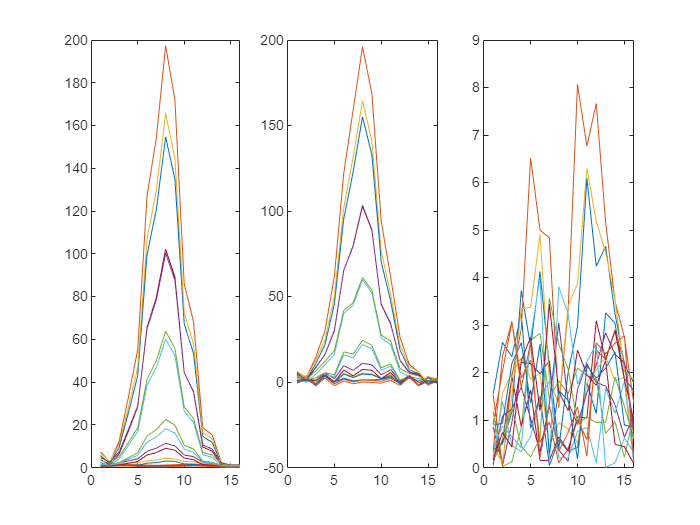


subplot(1,3,1), plot(shortwaves)
subplot(1,3,2), plot(real(rec0))
subplot(1,3,3), plot(abs(shortwaves-real(rec0)))

%frågor
    %För tröskelvärdet 0 sparade vi endast ett tal, vilket?
    %Svar: variabeln k=0 gav 1 värde (9,9)

    %Hur många tal sparade vi då tröskelvärdet var 1?
    %Svar: k=1 gav fyra värden

    %Hur många tal sparade vi då tröskelvärdet var 2?
    %Svar: 13 stycken värden

%Hur mycket komprimerar beror på tröskelvärdet, ju mindre destå mer
    %information kastar vi.
    % Sant

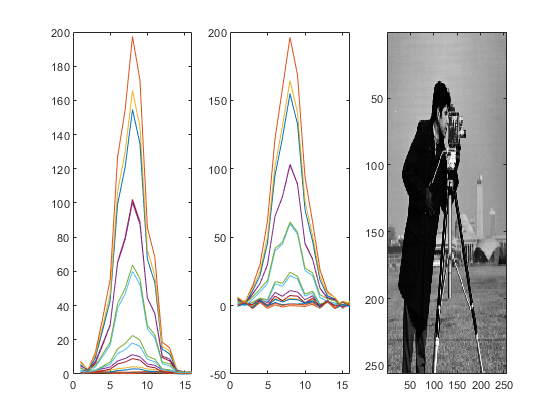

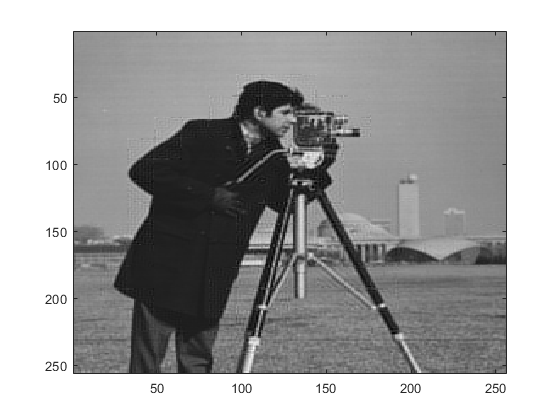

% 1.5
ORIGIM = imread('cameraman.tif');
ORIGIM = double(ORIGIM);

axis image;
colormap gray;
SFFTIMAGE = complex(zeros(size(ORIGIM)));
for k  = 1:16:size(ORIGIM,1)-15
 for m = 1:16:size(ORIGIM,2)-15
  SFFTIMAGE(k:k+15,m:m+15)=fftshift(fft2(ORIGIM(k:k+15,m:m+15)));
 end
end
RECIM = complex(zeros(size(ORIGIM)));
for mthres = 1:max(mask(:))+1
 for k  = 1:16:size(ORIGIM,1)-15
  for m = 1:16:size(ORIGIM,2)-15

    subimage = SFFTIMAGE(k:k+15,m:m+15) .* mask;

    %%RECIMAGE(k:k+15,m:m+15) = abs(ifft2(fftshift(subimage)));
    RECIMAGE(k:k+15,m:m+15) = ifft2(fftshift(subimage));
  end
 end
 axis image;
 colormap gray;
 figure(1);imagesc(ORIGIM)
 figure(2);imagesc(RECIMAGE);
 %drawnow
 pause(0.2)
end

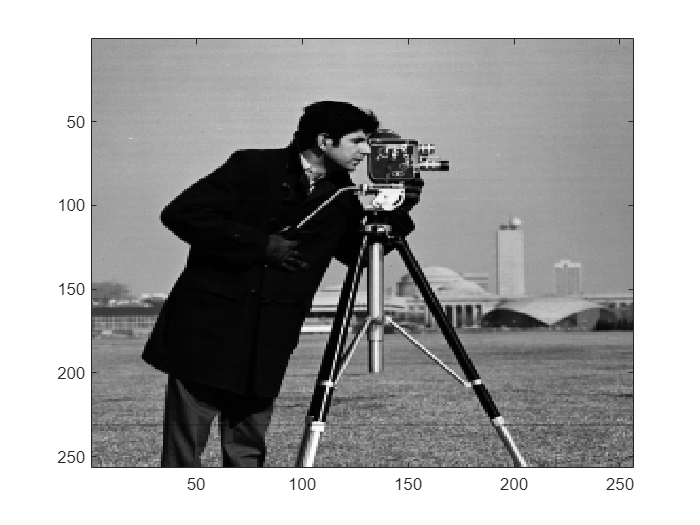

clf
axis image;
colormap gray;
imagesc(ORIGIM)

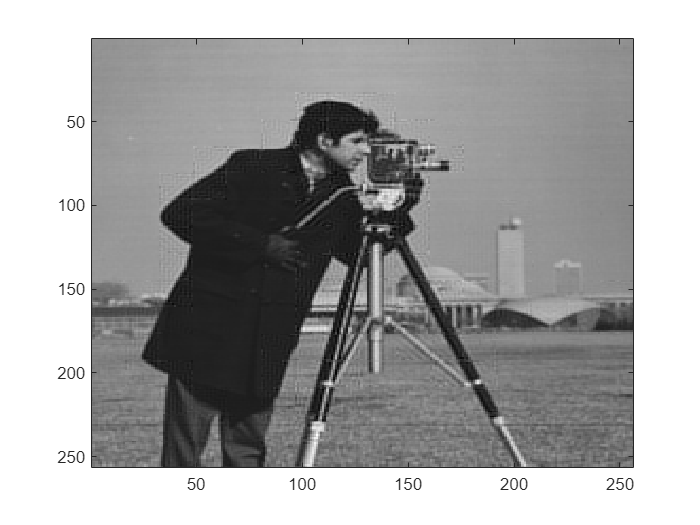

imagesc(RECIMAGE)

imwrite(ORIGIM/255, 'ORIGIM.tif')
imwrite(RECIMAGE/255, 'RECIMAGE.tif')